A =     1.0000         0         0         0
    2.0000    0.5000   -0.0018    0.0046
    3.0000    1.0000    0.0056    0.0023
    4.0000    0.5000    0.0320   -0.0011
    5.0000         0    0.0744    0.0041
    6.0000         0    0.1134    0.0024
    7.0000         0    0.1375    0.0012
    8.0000   -0.3333    0.1471   -0.0020
    9.0000   -0.6667    0.1396   -0.0065
   10.0000   -1.0000    0.0995   -0.0050


v =          0    0.0039    0.0078    0.0117    0.0156    0.0195    0.0234    0.0273    0.0312    0.0352    0.0391    0.0430    0.0469    0.0508    0.0547    0.0586    0.0625    0.0664    0.0703    0.0742    0.0781    0.0820    0.0859    0.0898    0.0938    0.0977    0.1016    0.1055    0.1094    0.1133    0.1172    0.1211    0.1250    0.1289    0.1328    0.1367    0.1406    0.1445    0.1484    0.1523    0.1562    0.1602    0.1641    0.1680    0.1719    0.1758    0.1797    0.1836    0.1875    0.1914


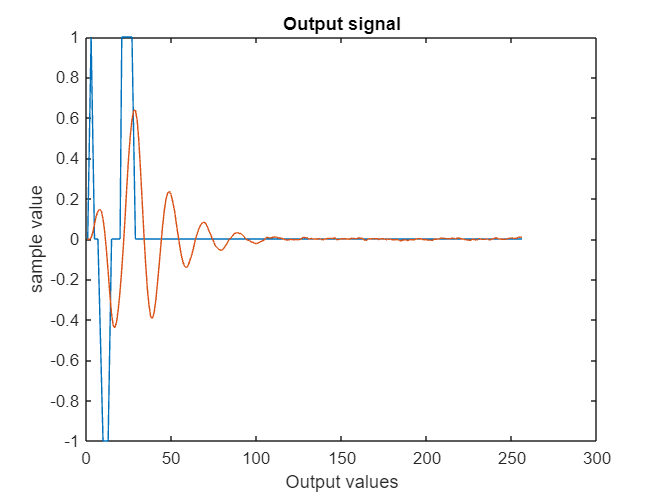

G =
 
    3 z
  -------
  3 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


A = load("MEASUREA.DAT")

t = A(:,1); % output
u = A(:,2); % input
y = A(:,3); % output
n = A(:,4); % noise


figure
plot(t, y)
xlabel("number of samples")
ylabel("sample value")
title("Time column")
hold on 
stairs(t, u)
xlabel("Input values")
ylabel("sample value")
title("Input signal")

plot(A(:,3))
xlabel("Output values")
ylabel("sample value")
title("Output signal")

n = 3;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)]
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)]
end


y_short = y(4:end);
Th = psi \ y_short;
T = 0.1;

G = tf([Th(4) Th(5) Th(6)],[1 Th(1) Th(2) Th(3)], T);

theta_hat = inv(psi'*psi)*psi'*y_short

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F) %frequency vector


figure
[MAG, PH] = bode(G, v)

bode(G)

G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,180/pi*(faza(1:end/2)))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Phase shift [degres]")
subplot(2,1,2), semilogx(v,20*log10(abs(G_jw(1:end/2))))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Gain[dB]")
